**Lab 1**

**Experiment 1.1)**

Part 1)

a)

Arr=[2709/1024 , 10583/4000 , 2024/765];
value=sqrt(7);
NewArr=abs(Arr-value);
disp(NewArr);

   1.0e-03 *

   0.243498564590716   0.001311064590670   0.000322922337315



[~,I] = min(NewArr)

I =      3


b)

format long
num = 3^301;
disp(num)

    4.106744371757652e+143



new_num = vpa(num)

$$new\_num = 4.1067443717576516082036169417484e+143$$

t)

x = 20/3 - 20 * (1/3);
disp(x)

     8.881784197001252e-16



Due to the fact that MATLAB rounds 1/3 because of digit limitation, the result isn't equal to 0.

s)

y = 10^16 + 1 - 10^16;
disp(y)

     0



Because 1 is ignored in comparison with 1e16, it is omitted in the final computation.

Part 2)

a,b,t)

format long
x1 = cosh(0.1)

x1 =    1.005004168055804


x2 = log(2)

x2 =    0.693147180559945


x3 = atan(1/2)

x3 =    0.463647609000806


Part 3)

a)

x_plot_1 = -2:0.1:2;
x_plot_2 = -2:0.001:2;
y_plot_1 = sin(1./(x_plot_1).^2);
y_plot_2 = sin(1./(x_plot_2).^2);

Now we use plot first.

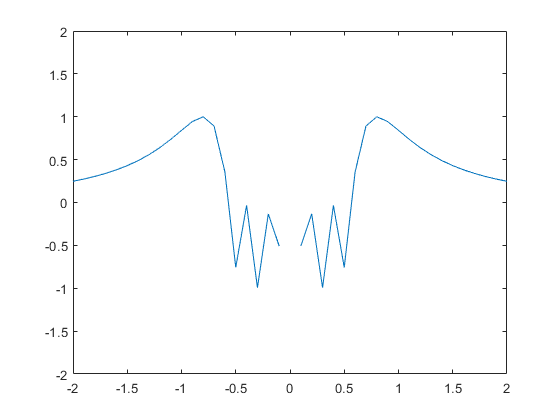

plot(x_plot_1,y_plot_1)
axis([-2 2 -2 2])

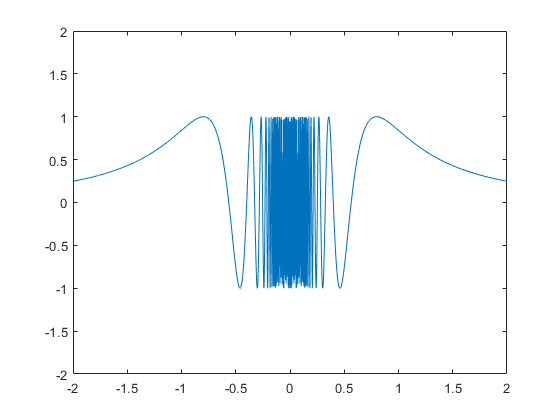

plot(x_plot_2,y_plot_2)
axis([-2 2 -2 2])

Now we shall use fplot and ezplot

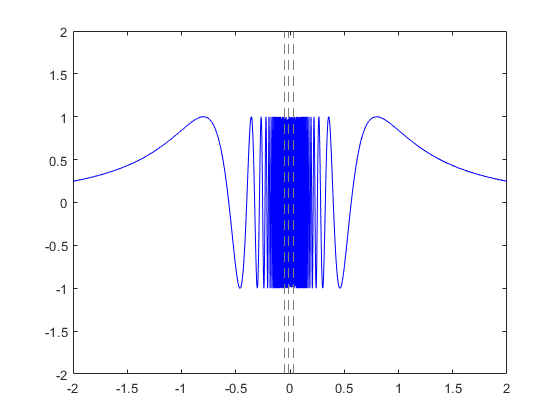

fplot(@(x) sin(1./(x.^2)),[-2 2],'b')
ylim([-2,2])

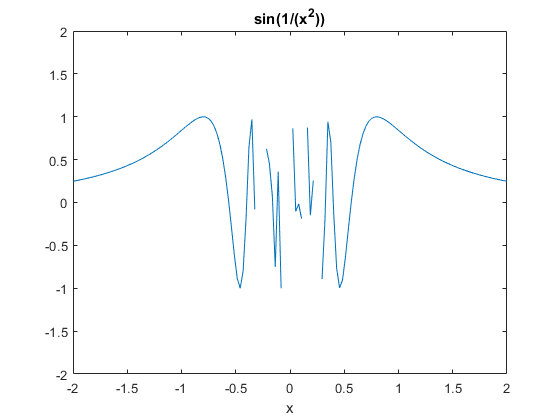

ezplot('sin(1/(x^2))')
axis([-2 2 -2 2])

According to previous plots, as it can be observed the plots using plot function with step=0.001 is more accurate than the one with step=0.1, however the latter is good enough.

Observed in the third plot, fplot performance is the best and the most accurate.

ezplot is not recommended.

b)

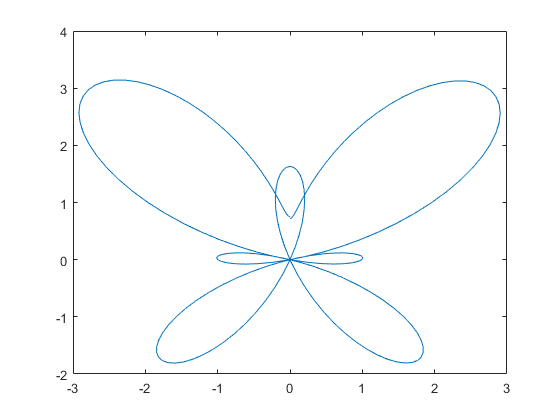

t1 = 0:pi/100:2*pi;
t2 = 0:pi/100:10*pi;
x1 = sin(t1).*(exp(cos(t1))-2.*cos(4*t1)+sin(t1./12).^5);
y1 = cos(t1).*(exp(cos(t1))-2.*cos(4*t1)+sin(t1./12).^5);
plot(x1,y1)

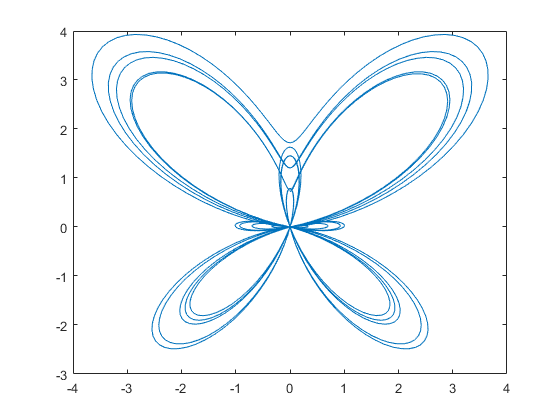

x2 = sin(t2).*(exp(cos(t2))-2.*cos(4*t2)+sin(t2./12).^5);
y2 = cos(t2).*(exp(cos(t2))-2.*cos(4*t2)+sin(t2./12).^5);
plot(x2,y2)

**Experiment 1.2)**

Part 1)

b1 = 2 * (3 < 8/4 + 2)^2 < (-2)^3

b1 = logical
   0


right side =2 ; while left side = -8  which is logically FALSE 

b2 = (5 + ~0)/3 == 3 - ~(10/5 - 2)

b2 = logical
   1


two sides of equal operator are computed seperately then equality is checked. in this case both sides equal 2 . which is logically TRUE. 

b3 = ~4 < 5|0 >= 12/6

b3 = logical
   1


~4 = 0 => 0<5 => True

0 >= 12/6 => False 

 True or False = True

b4 = -7<-5<-2&2+3<=15/3

b4 = logical
   0


-7<-5<-2 = False 

anything anded with False is False 

Part 2)

% Pascal
n=7;
I = eye(n);
I(:,1) = 1;
for i= 3:n
    for  j=2:i
        I(i,j)=I(i-1,j-1) +I(i-1,j);        
    end
end
I

I =      1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1


Part 3)

n = 500;
x = 1:n;
y = transpose(1:n);
z = x + y - ones(n,n);
out = 1./z;
disp(max(eig(out)))

   2.376896505684826



Part 4)

r1 = randi([10,30],1,20)

r1 =     19    11    24    10    11    20    12    27    27    25    13    23    20    30    23    26    19    19    27    11


sz = sum(rem(r1,2)==1);
r1(rem(r1,2)==1) =  randi([10,30],sz,1)

r1 =     12    13    24    10    18    20    12    27    26    11    18    21    20    30    18    26    23    23    16    19


cnt = 0;
while 1
    if(sum(rem(r1,2)==1)==0)
        break
    else
        cnt = cnt + 1;
        sz = sum(rem(r1,2)==1);
        r1(rem(r1,2)==1) =  randi([10,30],sz,1);
    end
end
r1

r1 =     12    10    24    10    18    20    12    30    26    18    18    12    20    30    18    26    18    14    16    20


formatSpec = 'The vector generated after %d iterations.\n';
fprintf(formatSpec,cnt)

The vector generated after 7 iterations.


Part 5)

### The code is in the mylcm.m